A = [-5 9;4 -7];

% compute the determinant of A
det_A = det(A)

det_A = -1.0000


% compute the inverse of A
inv_A = inv(A)

inv_A =     7.0000    9.0000
    4.0000    5.0000



% Define the matrix B
B = [2 1 3; 1 0 2; 3 2 1]

B =      2     1     3
     1     0     2
     3     2     1




% Compute the matrix of cofactors of A
[m, n] = size(B);
C = zeros(m,n);
for i = 1:m
    for j = 1:n
        D = B;
        D(i,:) = [];
        D(:,j) = [];
        C(i,j) = (-1)^(i+j) * det(D);
    end
end

cof_A = C

cof_A =    -4.0000    5.0000    2.0000
    5.0000   -7.0000   -1.0000
    2.0000   -1.0000   -1.0000



% Compute the adjoint matrix of A
adj_A = C'

adj_A =    -4.0000    5.0000    2.0000
    5.0000   -7.0000   -1.0000
    2.0000   -1.0000   -1.0000


B(1,:) = []

B =      1     0     2
     3     2     1


B(:,1) = []

B =      0     2
     2     1


## Visualize the span of two vectors

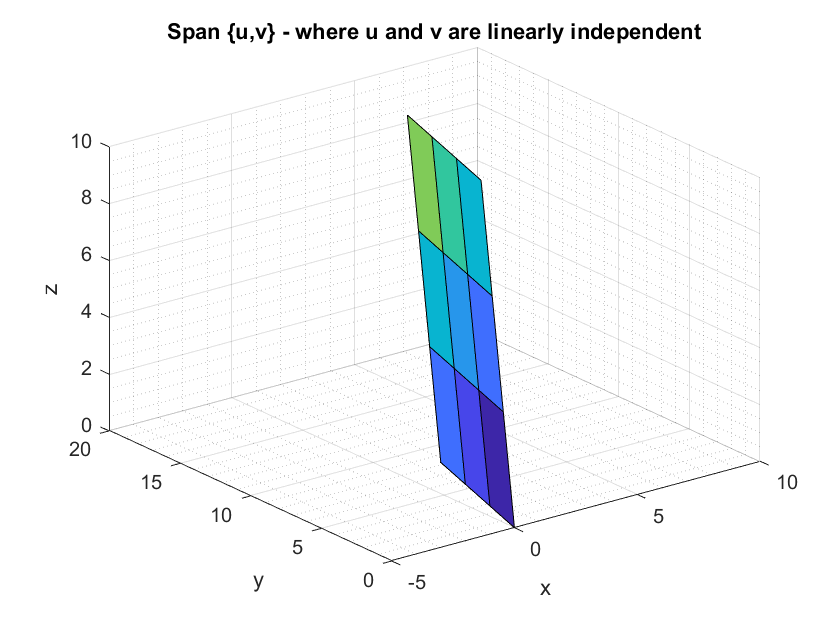

% Define two vectors in R^3
u = [3; 6; 2];
v = [-1; 0; 1];

% Define a range of values for the scalars a and b
a = 0:1:3;
b = 0:1:3;

% Create a grid of values for a and b
[A, B] = meshgrid(a, b);

% Compute the linear combinations of u and v for each value of a and b
X = A .* u(1) + B .* v(1);
Y = A .* u(2) + B .* v(2);
Z = A .* u(3) + B .* v(3);

% Plot the span of u and v as a surface in R^3
surf(X, Y, Z);
grid on; grid minor;
title("Span \{u,v\} - where u and v are linearly independent")
xlabel('x');
ylabel('y');
zlabel('z');

## u and v are linearly dependent

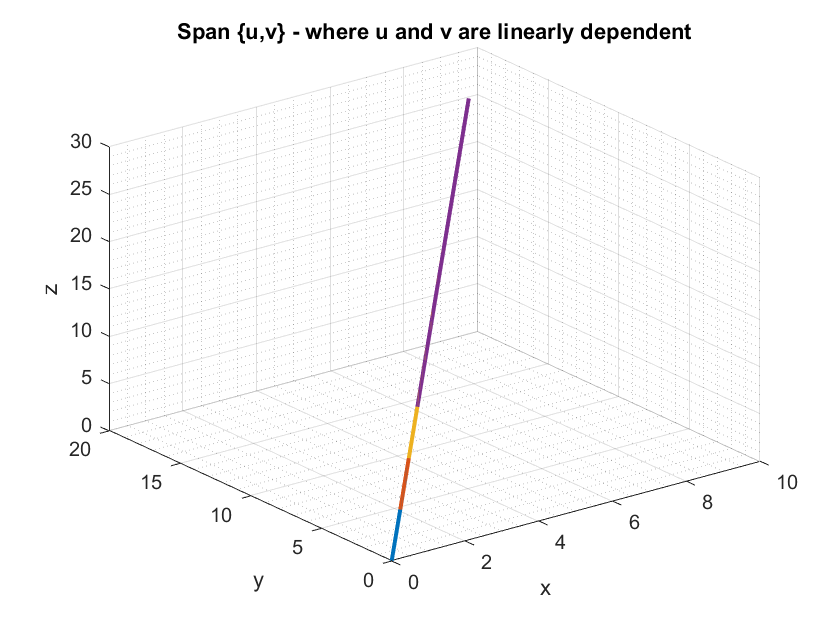

% Define two linearly dependent vectors in R^3
u = [1; 2; 3];
v = [2; 4; 6];

% Define a range of values for the scalar a
a = 0:1:3;

% Create a grid of values for a
[A, B] = meshgrid(a, a);

% Compute the linear combinations of u and v for each value of a
X = A .* u(1) + B .* v(1);
Y = A .* u(2) + B .* v(2);
Z = A .* u(3) + B .* v(3);

% Plot the span of u and v as a line in R^3
plot3(X, Y, Z, "LineWidth", 2);
grid on; grid minor;
xlabel('x');
ylabel('y');
zlabel('z');
title('Span \{u,v\} - where u and v are linearly dependent');

## Diagonalization

A = [1 3;4 2]

A =      1     3
     4     2


[eigens, values] = eig(A) % eigens - matrix of the eigenvectors

eigens =    -0.7071   -0.6000
    0.7071   -0.8000


values =     -2     0
     0     5


% values, the diagonal matrix of its corresponding eigenvalues
sym(eigens)

$$ans = \left(\begin{array}{cc} -\frac{\sqrt{2}}{2} & -\frac{3}{5}\\ \frac{\sqrt{2}}{2} & -\frac{4}{5} \end{array}\right)$$


$$A = PDP^{-1}$$


eigens_inverse = inv(eigens)

eigens_inverse =    -0.8081    0.6061
   -0.7143   -0.7143


A_1 = eigens*values*eigens_inverse

A_1 =      1     3
     4     2



$$A^8$$


A_8_1 = A^8

A_8_1 =       167557      167301
      223068      223324



$$A^8 = PD^8P^{-1}$$


A_8 = eigens*values.^8*eigens_inverse

A_8 =       167557      167301
      223068      223324


## PA = LU Decomposition

A = [0 1 1;1 2 1;2 7 9]

A =      0     1     1
     1     2     1
     2     7     9



[L, U, P] = lu(A, "matrix")

L =     1.0000         0         0
    0.5000    1.0000         0
         0   -0.6667    1.0000


U =     2.0000    7.0000    9.0000
         0   -1.5000   -3.5000
         0         0   -1.3333


P =      0     0     1
     0     1     0
     1     0     0


L*U

ans =     2.0000    7.0000    9.0000
    1.0000    2.0000    1.0000
         0    1.0000    1.0000


P*A

ans =      2     7     9
     1     2     1
     0     1     1


## A question

matrix_A = [1 3 3;-3 -5 -3;3 3 1]

matrix_A =      1     3     3
    -3    -5    -3
     3     3     1


[eigensA, valuesA] = eig(matrix_A) % eigens - matrix of the eigenvectors

eigensA =    -0.5774   -0.7876    0.4206
    0.5774    0.2074   -0.8164
   -0.5774    0.5802    0.3957


valuesA =     1.0000         0         0
         0   -2.0000         0
         0         0   -2.0000


% values, the diagonal matrix of its corresponding eigenvalues
sym(eigensA)

$$ans = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{3} & -\frac{886788218611235}{1125899906842624} & \frac{1894414937773747}{4503599627370496}\\ \frac{\sqrt{3}}{3} & \frac{7473924713418965}{36028797018963968} & -\frac{114893837276613}{140737488355328}\\ -\frac{\sqrt{3}}{3} & \frac{2612912285267569}{4503599627370496} & \frac{3564375710155739}{9007199254740992} \end{array}\right)$$

## eigen

syms lambda
matrix_B = [1-lambda 3 3;-3 -5-lambda -3;3 3 1-lambda]

$$matrix\_B = \left(\begin{array}{ccc} 1-\lambda & 3 & 3\\ -3 & -\lambda -5 & -3\\ 3 & 3 & 1-\lambda \end{array}\right)$$

result = det(matrix_B)

$$result = -\lambda^{3}-3\,\lambda^{2}+4$$

value = solve(result == 0, lambda)

$$value = \left(\begin{array}{c} -2\\ -2\\ 1 \end{array}\right)$$